# Model of a Pendulum Using Neural State-Space

## Workflow

- Design of experiments, data generation, and data preparation (already done, not covered here)

- Define and train neural state space 

- Evaluate the trained state space model

- Automatically generate the state function and its jacobian function

- Use neural state space model as an internal prediction model with Nonlinear MPC

- Simulate and generate code in MATLAB and Simulink

## Load training dataset

Datset was created by taking random initial states and generating N+1 experiments. Each experiment is uniformly sampled with 10 sampling intervals. Data sets U/X/Y are cell arrays of time tables where X and Y are merged to form measured outputs M. The last element in M is for validation during training. for training

load trainingdata;

## Create a continuous-time idNeuralStateSpace object 

TsNSS = 0;
obj = idNeuralStateSpace(2,NumInputs=1,Ts=TsNSS);

## Set hyper parameters of Multi-Layer Perceptron (MLP) network

obj.StateNetwork = createMLPNetwork(obj,'state',LayerSizes=[128 128],WeightsInitializer="glorot",BiasInitializer="zeros");

## Set training options

N = 100+1;
%Tx = (0:p)*DataSetSamplingInterval;
options = nssTrainingOptions('adam');
options.MaxEpochs = 500;
options.MiniBatchSize = N;
options.InputInterSample = 'spline';

## Train neural network



Training in progress (completed epoch/max epochs):        0/     500       1/     500       2/     500       3/     500       4/     500       5/     500       6/     500       7/     500       8/     500       9/     500      10/     500      11/     500      12/     500      13/     500      14/     500      15/     500      16/     500      17/     500      18/     500      19/     500      20/     500      21/     500      22/     500      23/     500      24/     500      25/     500      26/     500      27/     500      28/     500      29/     500      30/     500      31/     500      32/     500      33/     500      34/     500      35/     500      36/     500      37/     500      38/     500      39/     500      40/     500      41/     500      42/     500      43/     500      44/     500      45/     500      46/     500      47/     500      48/     500      49/     500      50/     500      51/     500      52/     500      53/     500      54/     500      55/   

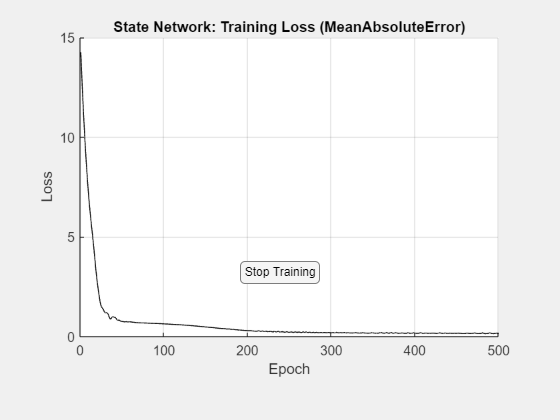

     500/     500



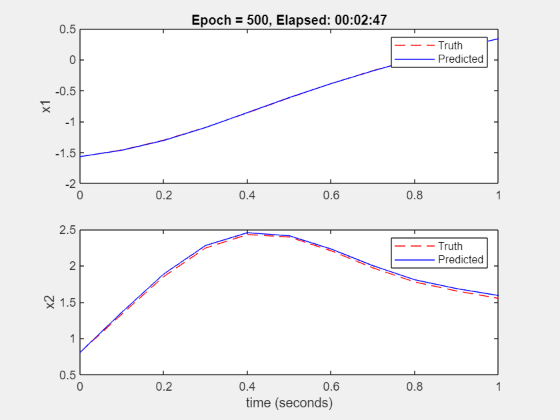

Generating estimation report...done.


obj = nlssest(U,M,obj,options,'UseLastExperimentForValidation',true);

## Evaluate trained state space system

rng(0)
xT = rand(2,1); uT = rand;
dxdt1 = evaluate(obj,xT,uT);
truthdxdt = pendulumFirstPrinciple(xT,uT);
abs(dxdt1-truthdxdt)./truthdxdt

ans =     0.0039
   -0.0217


## Generate MATLAB functions that implement the trained network in primnitive data types to represent the state function and its Jacobian function

generateMATLABFunction(obj,'nssStateFcn');

## Use StateFcn in NLMPC for Simulation in MATLAB

Elapsed time is 13.300181 seconds.


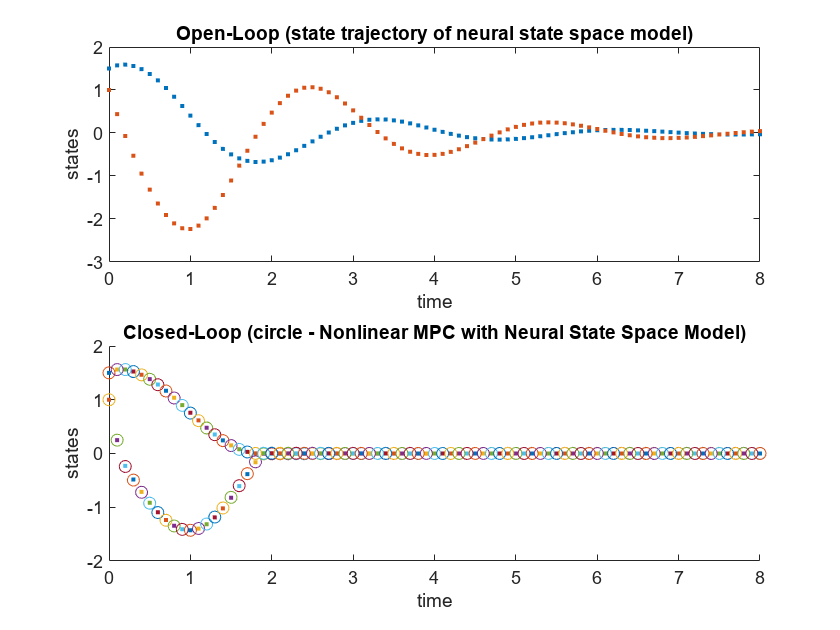

Elapsed time is 27.633448 seconds.


[nlmpcobj, x0] = pendulumControl('nssStateFcn','pendulumFirstPrinciple',TsNSS==0);

## Generate MEX from "nlmpcmove" with NSS prediction model

% [coredata,onlinedata] = getCodeGenerationData(nlmpcobj,x0,0);
% buildMEX(nlmpcobj,'pendulumMEX',coredata,onlinedata);

## Use StateFcn in NLMPC for Simulation in Simulink

mdl = 'pendulumNLMPC';
load_system(mdl);
open_system(mdl);
%sim(mdl);